# Import data from text file

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["t", "lambda", "f", "x", "y", "z"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
block = readtable("block.csv", opts);
clear opts

Statistics:

max(block.t)

ans = 10.2110

max(block.f)

ans = 16.6657

## Lambda and feedrate

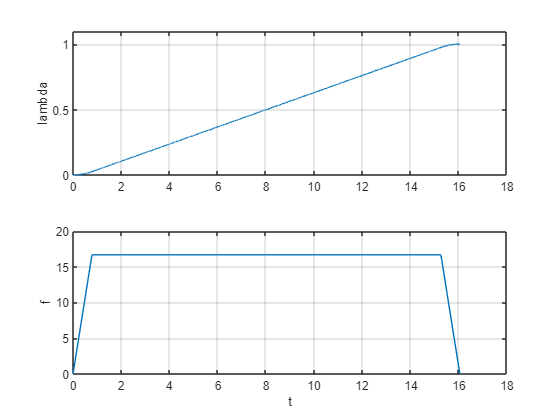

figure;
subplot(2,1,1);
plot(block.t, block.lambda)
ylim([0, 1.1]);
ylabel lambda;
grid on
subplot(2,1,2);
plot(block.t, block.f)
ylabel f
xlabel t
grid on

## Coordinates

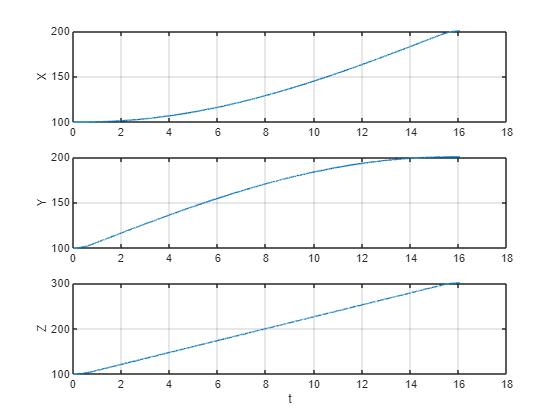

figure;
subplot(3,1,1);
plot(block.t, block.x)
grid on
ylabel X
subplot(3,1,2);
plot(block.t, block.y);
grid on
ylabel Y
subplot(3,1,3);
plot(block.t, block.z);
grid on
ylabel Z
xlabel t

## Trajectory

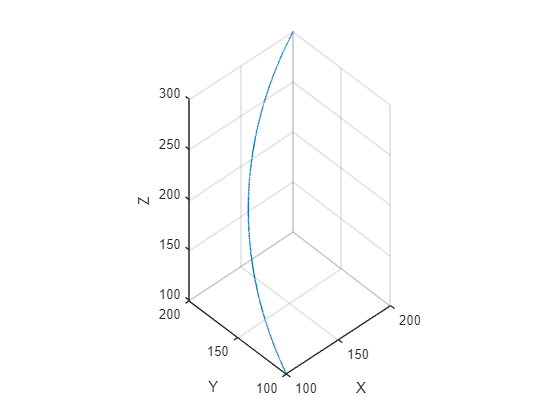

figure
plot3(block.x, block.y, block.z)
axis equal
grid on
xlabel X
ylabel Y
zlabel Z